videoReader = vision.VideoFileReader('sample.mp4');
videoPlayer = vision.VideoPlayer('Position',[100,100,500,400]);
foregroundDetector = vision.ForegroundDetector('NumTrainingFrames',10,...
                'InitialVariance',0.05);
blobAnalyzer = vision.BlobAnalysis('AreaOutputPort',false,...
                'MinimumBlobArea',70);

kalmanFilter

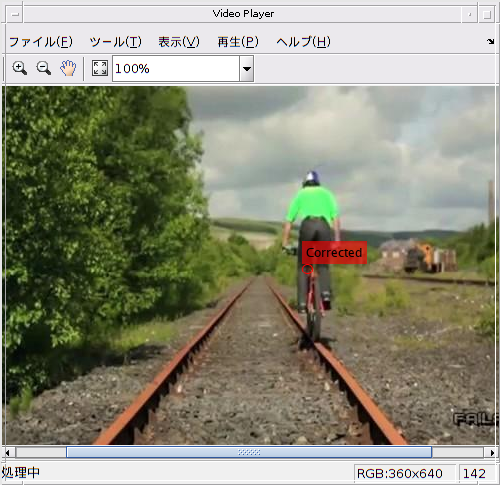

kalmanFilter = []; isTrackInitialized = false;
   while ~isDone(videoReader)
     colorImage  = step(videoReader);

     foregroundMask = step(foregroundDetector, rgb2gray(colorImage));
     detectedLocation = step(blobAnalyzer,foregroundMask);
     isObjectDetected = size(detectedLocation, 1) > 0;

     if ~isTrackInitialized
       if isObjectDetected
         kalmanFilter = configureKalmanFilter('ConstantAcceleration',...
                  detectedLocation(1,:), [1 1 1]*1e5, [25, 10, 10], 25);
         isTrackInitialized = true;
       end
       label = ''; circle = zeros(0,3);
     else
       if isObjectDetected
         predict(kalmanFilter);
         trackedLocation = correct(kalmanFilter, detectedLocation(1,:));
         label = 'Corrected';
       else
         trackedLocation = predict(kalmanFilter);
         label = 'Predicted';
       end
       circle = [trackedLocation, 5];
     end

     colorImage = insertObjectAnnotation(colorImage,'circle',...
                circle,label,'Color','red');
     step(videoPlayer,colorImage);
   end

release(videoPlayer);
release(videoReader);